[~,folder,~] = fileparts(pwd);
assert(strcmpi(folder,"defect reconstruction using coil and sensor array"), 'Not in project directory')
addpath('../../DCS_functions')

clear

#### Coil

Coil.num = 16;
Coil.inner_radius = 7.92e-3 * ones(1,Coil.num); % (m)
Coil.outer_radius = 10.0e-3 * ones(1,Coil.num); % (m)
Coil.length       = 10.0e-3 * ones(1,Coil.num); % (m)
Coil.N_turns = 100 * ones(1,Coil.num);

coil_spacing = 20e-3; % (m)
coil_z       = 13e-3; % (m)

d = coil_spacing * (sqrt(Coil.num) - 1) / 2;
l = linspace(-d, d, 4);
[x, y] = meshgrid(l,l);
x = reshape(x.', 1, []);
y = reshape(y.', 1, []);
coil_pos = [x; y; coil_z*ones(1,Coil.num)];

Coil = SetPositionRotation3D(Coil, coil_pos.');

clear coil_spacing coil_z coil_pos d l x y 

#### Sensor

Sensor.num = 81;
Sensor.side_length = 3e-3;

sensor_spacing = 10e-3; % (m)
sensor_z       = 3e-3; % (m)

d = sensor_spacing * (sqrt(Sensor.num) - 1) / 2;
l = linspace(-d, d, sqrt(Sensor.num));
[x, y] = meshgrid(l,l);
x = reshape(x', 1, []);
y = reshape(y', 1, []);
sensor_pos = [x; y; sensor_z*ones(1,Sensor.num)];

Sensor = SetPositionRotation3D(Sensor, sensor_pos.');

clear sensor_spacing sensor_z sensor_pos d l x y

#### Model

plate.l = 120e-3; % (m)
plate.h = 5e-3;  % (m)

n_l = 30; % number of elements in x and y direction
x = linspace(-plate.l/2, plate.l/2, n_l+1);
y = x;
z = [-plate.h -plate.h/2 0];

Model = BuildModel3D('Cuboid', x,y,z);

build model took 0.20 seconds


clear plate n_l x y z

Model.conductivity = 3.774e7 * ones(1,Model.num_elems); % (S/m)
Model.relative_permittivity = 1 * ones(1,Model.num_elems); % (1)
Model.relative_permeability = 1 * ones(1,Model.num_elems); % (1)

#### Plot world

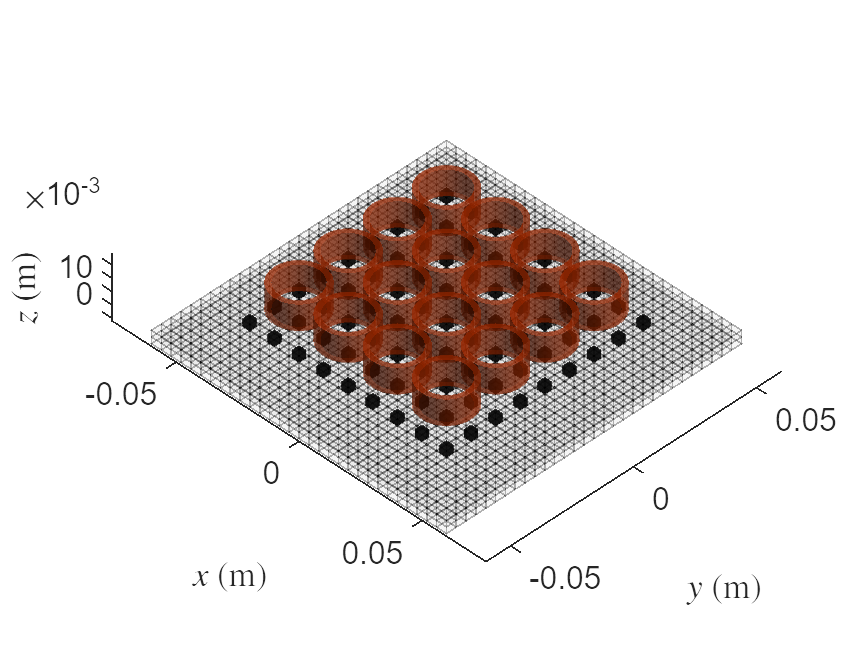

figure
PlotWorld3D(Model, Coil, Sensor)

#### Governing equation

GoverningEquation = BuildGoveringEquation3D(Model, Coil, Sensor);
GoverningEquation.frequency = 250; % (Hz)

#### Compute sensivity matrix

tic
[GoverningEquation, B_bar] = SolveB(GoverningEquation, 0);
B_bar = permute(B_bar, [1 3 2]);
t = toc;
fprintf('Compute no defect took %.2f seconds\n', t)
cr = join(repmat(sprintf("\b"),50,1),'');

S = zeros(Sensor.num*3, Model.num_elems, Coil.num);
for j = 1:Model.num_elems
    tic
    [GoverningEquation, B] = SolveB(GoverningEquation, j);
    B = permute(B, [1 3 2]);
    t = toc;
    fprintf(cr + 'Compute element %d defect took %.2f seconds\n', j, t); 

    S(:,j,:) = B - B_bar;
end

elems_center = Model.elems_center;

fname = sprintf('precompute_%s.mat', datetime('now','Format','MMdd-HHmm'));
save(fname, 'S', 'elems_center')

clear t cr j fname B_bar B S elems_center 

function [GE, B] = SolveB(GE, defect_elem)

n = size(GE.Sigma,1) / 3;
num_coils = size(GE.L_E_coil,1);

I_E = speye(num_coils);

if ~isfield(GE, 'A')
    jomega = 1i * 2*pi * GE.frequency;

    Q_c = GE.Q_c(1:n-1, :);
    Q_p = zeros(1,n);
    Q_p(1) = 1;

    GE.A = [speye(3*n) + jomega * GE.Sigma * GE.Alpha_C_model  GE.Sigma * GE.Gamma
                                                          Q_c         zeros(n-1,n)
                                                 zeros(1,3*n)                  Q_p];
    GE.B = [-jomega * GE.Sigma * GE.Alpha_E_model * I_E
                                     zeros(n,num_coils)];
end

if canUseGPU
    GE.A = gpuArray(GE.A);
    GE.B = gpuArray(GE.B);
    GE.Beta_E_sensor = gpuArray(GE.Beta_E_sensor);
    GE.Beta_C_sensor = gpuArray(GE.Beta_C_sensor);
end

if defect_elem ~= 0
    idxs = defect_elem*3-2 : defect_elem*3;

    A_temp = GE.A(idxs, :);
    B_temp = GE.B(idxs, :);

    GE.A(idxs,:) = 0;
    GE.A(idxs,idxs) = eye(3);
    GE.B(idxs,:) = 0;
end

x = GE.A \ GE.B;
x = mat2cell(x, [3*n n]);
J = x{1};
B = GE.Beta_E_sensor * I_E + GE.Beta_C_sensor * J;
B = gather(B);

if defect_elem ~= 0
    GE.A(idxs, :) = A_temp;
    GE.B(idxs, :) = B_temp;
end

end